# 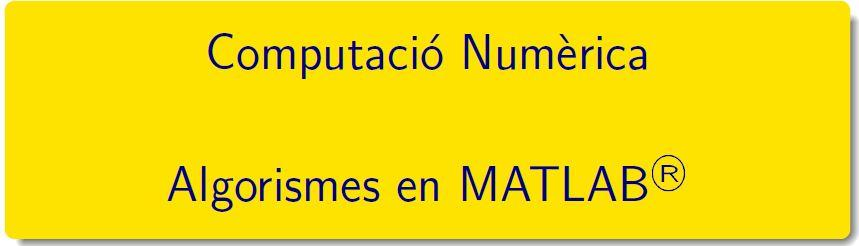

===========================================================================

# Pràctica 1 - Conceptes Bàsics (revisió)

## 1. Introducció a MATLAB®

[ Cleve’s Corner: Cleve Moler on Mathematics and Computing](https://blogs.mathworks.com/cleve/)

[A Brief History of MATLAB](https://es.mathworks.com/company/newsletters/articles/a-brief-history-of-matlab.html?s_tid=srchtitle)

## 2. Exemple mètode iteratiu: convergència 

El mètode iteratiu següent: convergeix a $\sqrt{2}$

                
$$x_k=\displaystyle\frac{1}{2}\left (x_{k-1}+\displaystyle\frac{2}{x_{k-1}}\right )\quad k\ge 1\ i\ x_0=3\,.$$


Calculeu els sis primers iterats, totes les iteracions en un vector, resultat en una estructura table.

format longG
x(1) = 3;
for k = 2:7
    x(k) = (x(k-1)+2/x(k-1))/2;
end
ea = abs(x-sqrt(2));
er = ea / sqrt(2);
R = [x; ea; er]';
T = array2table(R,...
    'VariableNames',{'x_k','ea_k','er_k'}); disp(T)

## 5. Algorismes: Estabilitat numèrica i problemes ben condicionats

### [Funcions en Scripts o en Live scripts](https://es.mathworks.com/help/matlab/ref/function.html)

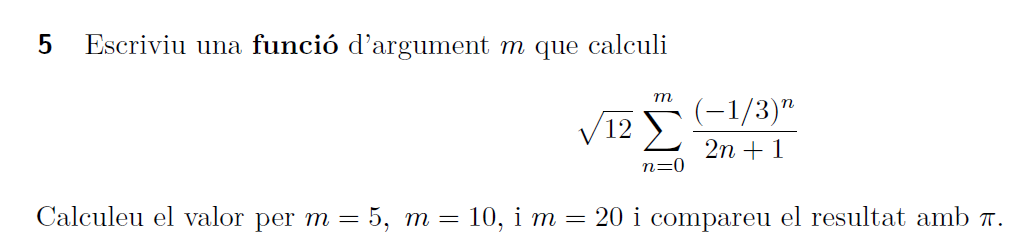

% Per fer (ja està feta)

### [Funcions anònimes](https://es.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html)

`h = @(``arglist``)``anonymous_function`

**6**   Avalueu les funcions  $\displaystyle f(x)=\sqrt{x^2+1}-1\,,\quad\quad
g(x)=x^2/{\left( \sqrt{x^2+1}+1\right) }$ per a la successió de valors de $x_n= 8^{-n}\,,\ n\geq 1\,.$ Encara que $f(x)=g(x)$, l'ordinador dóna resultats diferents. 

Quins resultats són de fiar i quins no? Per què?  Expliqueu la vostra resposta

f = @(x)sqrt(x.^2+1)-1;
g = @(x)(x.^2)./(sqrt(x.^2+1)+1);
xn = @(x)8.^(-x);
input = xn(0:15);
fout = f(input);
gout = g(input);
table = [0:15;input; fout; gout; (fout-gout)]';
T = array2table(table, 'VariableNames',{'X', 'Input', 'F Output', 'G Output', 'Difference'});
disp(T)

    X       Input        F Output      G Output     Difference 
    __    __________    __________    __________    ___________

     0             1       0.41421       0.41421     5.5511e-17
     1         0.125     0.0077822     0.0077822    -6.5052e-17
     2      0.015625    0.00012206    0.00012206     -8.328e-17
     3     0.0019531    1.9073e-06    1.9073e-06    -3.4694e-18
     4    0.00024414    2.9802e-08    2.9802e-08    -1.3235e-23
     5    3.0518e-05    4.6566e-10    4.6566e-10     1.0842e-19
     6    3.8147e-06     7.276e-12     7.276e-12      2.647e-23
     7    4.7684e-07    1.1369e-13    1.1369e-13     6.4623e-27
     8    5.9605e-08    1.7764e-15    1.7764e-15     1.5777e-30
     9    7.4506e-09             0    2.7756e-17    -2.7756e-17
    10    9.3132e-10             0    4.3368e-19    -4.3368e-

**12** **Càlcul d'integrals per recurrència**	

	Per calcular les integrals$\displaystyle I_{n}=\int_{0}^{1} x^n e^{x-1}dx\,,\quad n\ge~1\,,$ 	dispossem de dos m\`{e}todes iteratius diferents:

	
$$$$\begin{array}{llrr}
	\text{ a)}\quad I_{n-1}&=\displaystyle\frac{1-I_n}{n}, & n\ge 2 &{\rm\ on\ }I_{50}=0\,,\\  & & & \\
	\text{ b)}\quad I_n&=1-nI_{n-1}, & n\ge 2 &{\rm\ on\ }I_1=1/e\,.
	\end{array}$$$$


	Calculeu $$I_{30}$\,$ pels dos mètodes. Obteniu els mateixos resultats ? Sabrieu donar una explicació?

f2 = @(x) x^2 * exp(x-1);
f3 = @(x) x^3 * exp(x-1);
f4 = @(x) x^4 * exp(x-1);
f15 = @(x) x^15 * exp(x-1);
f25 = @(x) x^25 * exp(x-1);
input = 0:1;
fplot(f2, input);

- apartat a)

hold on
fplot(f3, input);

fplot(f4, input)

fplot(f15, input)

fplot(f25, input)

hold off

- apartat b)

- valor aproximat per integració numèrica

- Taula comparativa de resultats

- Taula comparativa d'errors

% resolt la setmana anterior

## Pràctica

## 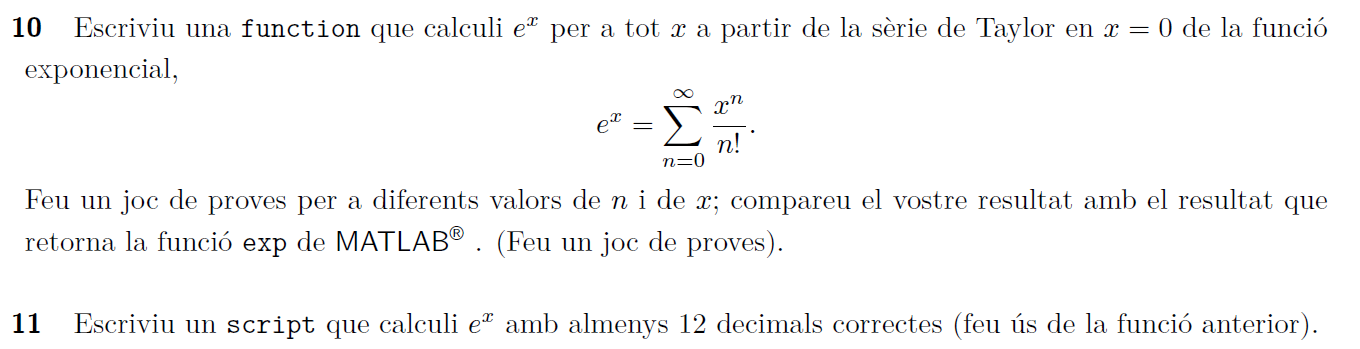 

decimals_correctes = @(x)fix(-log10(2*x)); 
error_absolut = @(x, y) abs(x - y);

x = -7;
result = 0;
it = 0;
while decimals_correctes(error_absolut(exp(x), result)) < 12 && it < 1000
    result = result + (x^it / factorial(it) );
    it = it + 1;
end
result, exp(x), it

result =    0.00091188


ans =    0.00091188


it =     38


`Document preparat per M. Àngela Grau Gotés, 24 de febrer de 2022`